% range, startpoint and target
Xmin=-50;           %range of image
Ymin=-10;
Xmax=60;
Ymax=30;
start_point=[-40 ; 10]; % start point of all nodes
var=5;% point generate variance
wt=[200 ; 10]; % target point location

% define wall models
syms P1(z) P2(z)
P1(z)= 0.8*(z)^2 +20;
P2(z)= 0.5*(z)^2 +10;
Pd1=diff(P1);% derivative of wall equations
Pd2=diff(P2);
steps1=200;
steps2=steps1;
z1=linspace(Xmin,Xmax,steps1).';
z2=linspace(Xmin,Xmax,steps2).';
yP1=P1(z1);
yP2=P2(z2);
curvexy1=[z1 yP1];
curvexy2=[z2 yP2];
syms y1 x1 y2 x2 cx cy real

% solve chord problem
node_x=-2;
node_y=17;
%%% Tangent Chord solution %%%%
% equations and conditions of solving chord problem
y1=P1(x1);
y2=P2(x2);
eqns=[(y1-cy)*Pd1(x1)==-(x1-cx), (y2-cy)*Pd2(x2)==-(x2-cx)...
    (x1-cx)^2+(y1-cy)^2==(x2-cx)^2+(y2-cy)^2, (y1-node_y)*(x2-node_x)==(y2-node_y)*(x1-node_x)];
[p1_x, p2_x, centre_x, centre_y] = vpasolve(eqns,[x1 x2 cx cy]);       

p1_y=P1(p1_x);
p2_y=P2(p2_x);
p1=[p1_x.'; p1_y.'];
p2=[p2_x.'; p2_y.'];
% filter (identify right solution manually)
chord_length_all=vecnorm(double(p1-p2));
[chord,chord_ind]=min(chord_length_all);
% chord_length(k,t)=chord;
p1_point=p1(:,chord_ind);
p2_point=p2(:,chord_ind);
center=[centre_x(chord_ind);centre_y(chord_ind)];
r=norm([p1_point(1)-center(1),p1_point(2)-center(2)]);


figure;
% subplot(1,2,1)

hold on;
% walls
plot(curvexy1(:,1),curvexy1(:,2),'k','LineWidth',1)
plot(curvexy2(:,1),curvexy2(:,2),'k','LineWidth',1)
scatter(node_x,node_y,100,'.','blue');
scatter(center(1),center(2),'*','r')
circle(center(1),center(2),r);
line([p1_point(1);center(1)],[p1_point(2);center(2)],'color',[0.4,0,0.6],'LineStyle',':')
line([p2_point(1);center(1)],[p2_point(2);center(2)],'color',[0.4,0,0.6],'LineStyle',':')
line([p1_point(1);p2_point(1)],[p1_point(2);p2_point(2)],'color',[1 0 0],'LineWidth',0.9)



% solve chord problem
node_x=3;
node_y=20;
%%% Tangent Chord solution %%%%
% equations and conditions of solving chord problem
y1=P1(x1);
y2=P2(x2);
eqns=[(y1-cy)*Pd1(x1)==-(x1-cx), (y2-cy)*Pd2(x2)==-(x2-cx)...
    (x1-cx)^2+(y1-cy)^2==(x2-cx)^2+(y2-cy)^2, (y1-node_y)*(x2-node_x)==(y2-node_y)*(x1-node_x)];
[p1_x, p2_x, centre_x, centre_y] = vpasolve(eqns,[x1 x2 cx cy]);       

p1_y=P1(p1_x);
p2_y=P2(p2_x);
p1=[p1_x.'; p1_y.'];
p2=[p2_x.'; p2_y.'];
% filter (identify right solution manually)
chord_length_all=vecnorm(double(p1-p2));
[chord,chord_ind]=min(chord_length_all);
% chord_length(k,t)=chord;
p1_point=p1(:,chord_ind);
p2_point=p2(:,chord_ind);
center=[centre_x(chord_ind);centre_y(chord_ind)];
r=norm([p1_point(1)-center(1),p1_point(2)-center(2)]);


scatter(node_x,node_y,100,'.','blue');
scatter(center(1),center(2),'*','r')
circle(center(1),center(2),r);
line([p1_point(1);center(1)],[p1_point(2);center(2)],'color',[0.4,0,0.6],'LineStyle',':')
line([p2_point(1);center(1)],[p2_point(2);center(2)],'color',[0.4,0,0.6],'LineStyle',':')
line([p1_point(1);p2_point(1)],[p1_point(2);p2_point(2)],'color',[1 0 0],'LineWidth',0.9)



% solve chord problem
node_x=1;
node_y=16;
%%% Tangent Chord solution %%%%
% equations and conditions of solving chord problem
y1=P1(x1);
y2=P2(x2);
eqns=[(y1-cy)*Pd1(x1)==-(x1-cx), (y2-cy)*Pd2(x2)==-(x2-cx)...
    (x1-cx)^2+(y1-cy)^2==(x2-cx)^2+(y2-cy)^2, (y1-node_y)*(x2-node_x)==(y2-node_y)*(x1-node_x)];
[p1_x, p2_x, centre_x, centre_y] = vpasolve(eqns,[x1 x2 cx cy]);       

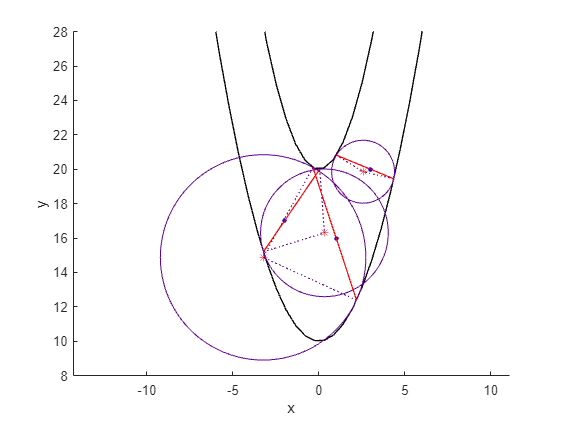

p1_y=P1(p1_x);
p2_y=P2(p2_x);
p1=[p1_x.'; p1_y.'];
p2=[p2_x.'; p2_y.'];
% filter (identify right solution manually)
chord_length_all=vecnorm(double(p1-p2));
[chord,chord_ind]=min(chord_length_all);
% chord_length(k,t)=chord;
p1_point=p1(:,chord_ind);
p2_point=p2(:,chord_ind);
center=[centre_x(chord_ind);centre_y(chord_ind)];
r=norm([p1_point(1)-center(1),p1_point(2)-center(2)]);

scatter(node_x,node_y,100,'.','blue');
scatter(center(1),center(2),'*','r')
circle(center(1),center(2),r);
line([p1_point(1);center(1)],[p1_point(2);center(2)],'color',[0.4,0,0.6],'LineStyle',':')
line([p2_point(1);center(1)],[p2_point(2);center(2)],'color',[0.4,0,0.6],'LineStyle',':')
line([p1_point(1);p2_point(1)],[p1_point(2);p2_point(2)],'color',[1 0 0],'LineWidth',0.9)
xlabel('x')
ylabel('y')
% axis (xy limit)
axis([-10 10 8 28]);
% grid on;
axis equal
hold off;

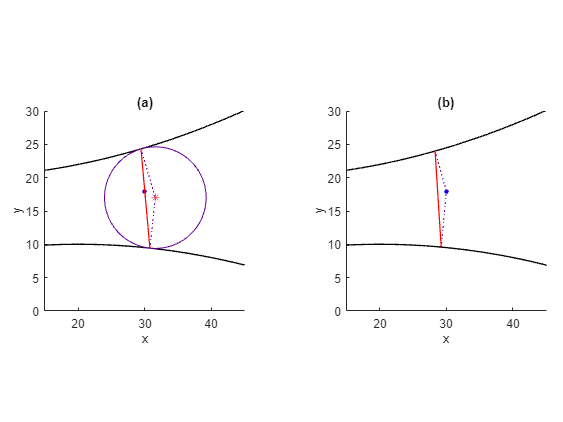

% range, startpoint and target
Xmin=-50;           %range of image
Ymin=-10;
Xmax=60;
Ymax=30;
start_point=[-40 ; 10]; % start point of all nodes
var=5;% point generate variance
wt=[200 ; 10]; % target point location

% define wall models
syms P1(z) P2(z)
P1(z)= 0.005*(z)^2 +20;
P2(z)= -0.005*(z-20)^2 +10;
Pd1=diff(P1);% derivative of wall equations
Pd2=diff(P2);
steps1=200;
steps2=steps1;
z1=linspace(Xmin,Xmax,steps1).';
z2=linspace(Xmin,Xmax,steps2).';
yP1=P1(z1);
yP2=P2(z2);
curvexy1=[z1 yP1];
curvexy2=[z2 yP2];
syms y1 x1 y2 x2 cx cy real
% solve chord problem
node_x=30;
node_y=18;




%%% Tangent Chord solution %%%%
% equations and conditions of solving chord problem
y1=P1(x1);
y2=P2(x2);
eqns=[(y1-cy)*Pd1(x1)==-(x1-cx), (y2-cy)*Pd2(x2)==-(x2-cx)...
    (x1-cx)^2+(y1-cy)^2==(x2-cx)^2+(y2-cy)^2, (y1-node_y)*(x2-node_x)==(y2-node_y)*(x1-node_x)];
[p1_x, p2_x, centre_x, centre_y] = vpasolve(eqns,[x1 x2 cx cy]);       
p1_y=P1(p1_x);
p2_y=P2(p2_x);
p1=[p1_x.'; p1_y.'];
p2=[p2_x.'; p2_y.'];
% filter (identify right solution manually)
chord_length_all=vecnorm(double(p1-p2));
[chord,chord_ind]=min(chord_length_all);
% chord_length(k,t)=chord;
p1_point=p1(:,chord_ind);
p2_point=p2(:,chord_ind);
center=[centre_x(chord_ind);centre_y(chord_ind)];
r=norm([p1_point(1)-center(1),p1_point(2)-center(2)]);

close all
ha = tight_subplot(1,2,[.02 .18],[.01 .01],[.08 .03]);
figure;
axes(ha(1));
set(ha(1), 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
set(ha(1), 'YTickMode', 'auto', 'YTickLabelMode', 'auto');
hold on;
% walls
plot(curvexy1(:,1),curvexy1(:,2),'k','LineWidth',1)
plot(curvexy2(:,1),curvexy2(:,2),'k','LineWidth',1)
scatter(node_x,node_y,100,'.','blue');
scatter(center(1),center(2),'*','r')
circle(center(1),center(2),r);
line([p1_point(1);center(1)],[p1_point(2);center(2)],'color',[0.4,0,0.6],'LineStyle',':')
line([p2_point(1);center(1)],[p2_point(2);center(2)],'color',[0.4,0,0.6],'LineStyle',':')
line([p1_point(1);p2_point(1)],[p1_point(2);p2_point(2)],'color',[1 0 0],'LineWidth',0.9)
% axis (xy limit)
title('(a)')
xlabel('x')
ylabel('y')
xlim([15 45])
ylim([0 30])
% axis([15 45 0 30]);
% grid on;
axis square
hold off;




%%% Perpendicular solution %%%%
% equations and conditions of solving chord problem
y1=P1(x1);
y2=P2(x2);
eqns=[(y1-node_y)*Pd1(x1)==-(x1-node_x), (y2-node_y)*Pd2(x2)==-(x2-node_x)];
[p1_x, p2_x] = vpasolve(eqns,[x1 x2]);
p1_y=P1(p1_x);
p2_y=P2(p2_x);
p1=[p1_x.'; p1_y.'];
p2=[p2_x.'; p2_y.'];


axes(ha(2));
set(ha(2), 'XTickMode', 'auto', 'XTickLabelMode', 'auto');
set(ha(2), 'YTickMode', 'auto', 'YTickLabelMode', 'auto');
hold on;
% walls
plot(curvexy1(:,1),curvexy1(:,2),'k','LineWidth',1)
plot(curvexy2(:,1),curvexy2(:,2),'k','LineWidth',1)
scatter(node_x,node_y,100,'.','blue');
line([p1(1);node_x],[p1(2);node_y],'color',[0.4,0,0.6],'LineStyle',':')
line([p2(1);node_x],[p2(2);node_y],'color',[0.4,0,0.6],'LineStyle',':')
line([p1(1);p2(1)],[p1(2);p2(2)],'color',[1 0 0],'LineWidth',0.9)
% axis (xy limit)
xlim([15 45])
ylim([0 30])
title('(b)')
xlabel('x')
ylabel('y')
% axis([15 45 0 30]);
% grid on;
axis square
hold off;

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit,'Color',[0.4,0,0.6]);
end
